# Analysing and plotting PPG pulses

Copyright (C) 2022 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIOVASCULAR AND RESPIRATORY MONITORING DEVICES

The this section is based on a code PulseAnalyze.m developed by Peter H. Charlton.

% Changing the path from main_folder to a particular chapter
main_path=fileparts(which('Main_Content.mlx'));
if ~isempty(main_path)
    %addpath(append(main_path,'/Chapter2'))
    cd (append(main_path,'/Chapter6/PulseAnalyze'))
    addpath(append(main_path,'/Service'))
end
SAVE_FLAG=1; % saving the figures in a file

## Introduction

In this notebook, we present pulse analysis based on the software package developed by Peter H. Charlton. In the end of the notebook, we show examples of realistic red and infrared PPG signals.

## Analysis of the signal using PulseAnalyse code

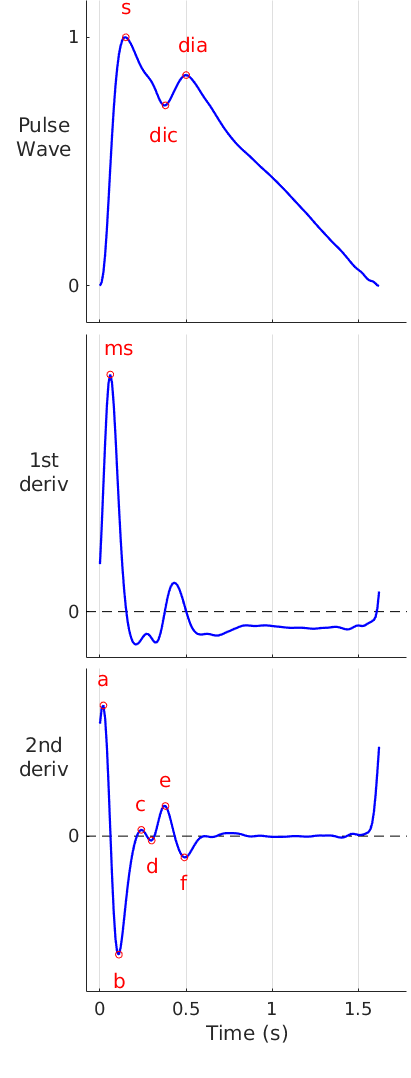

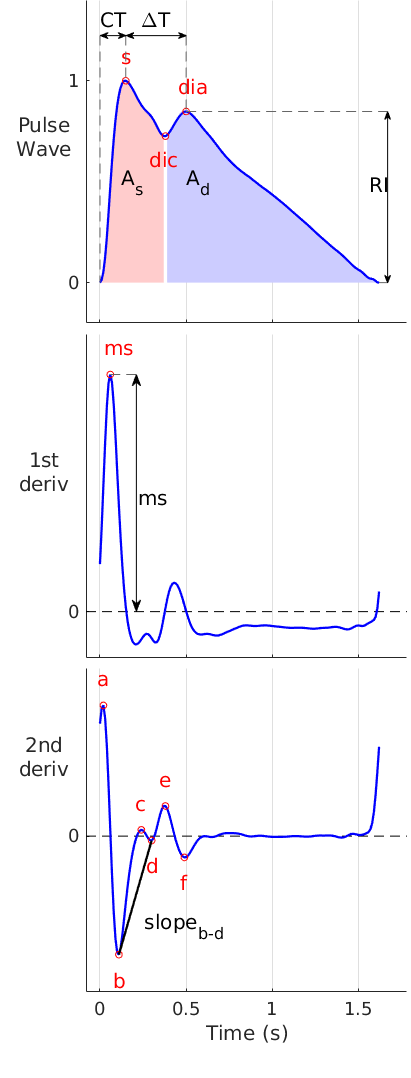

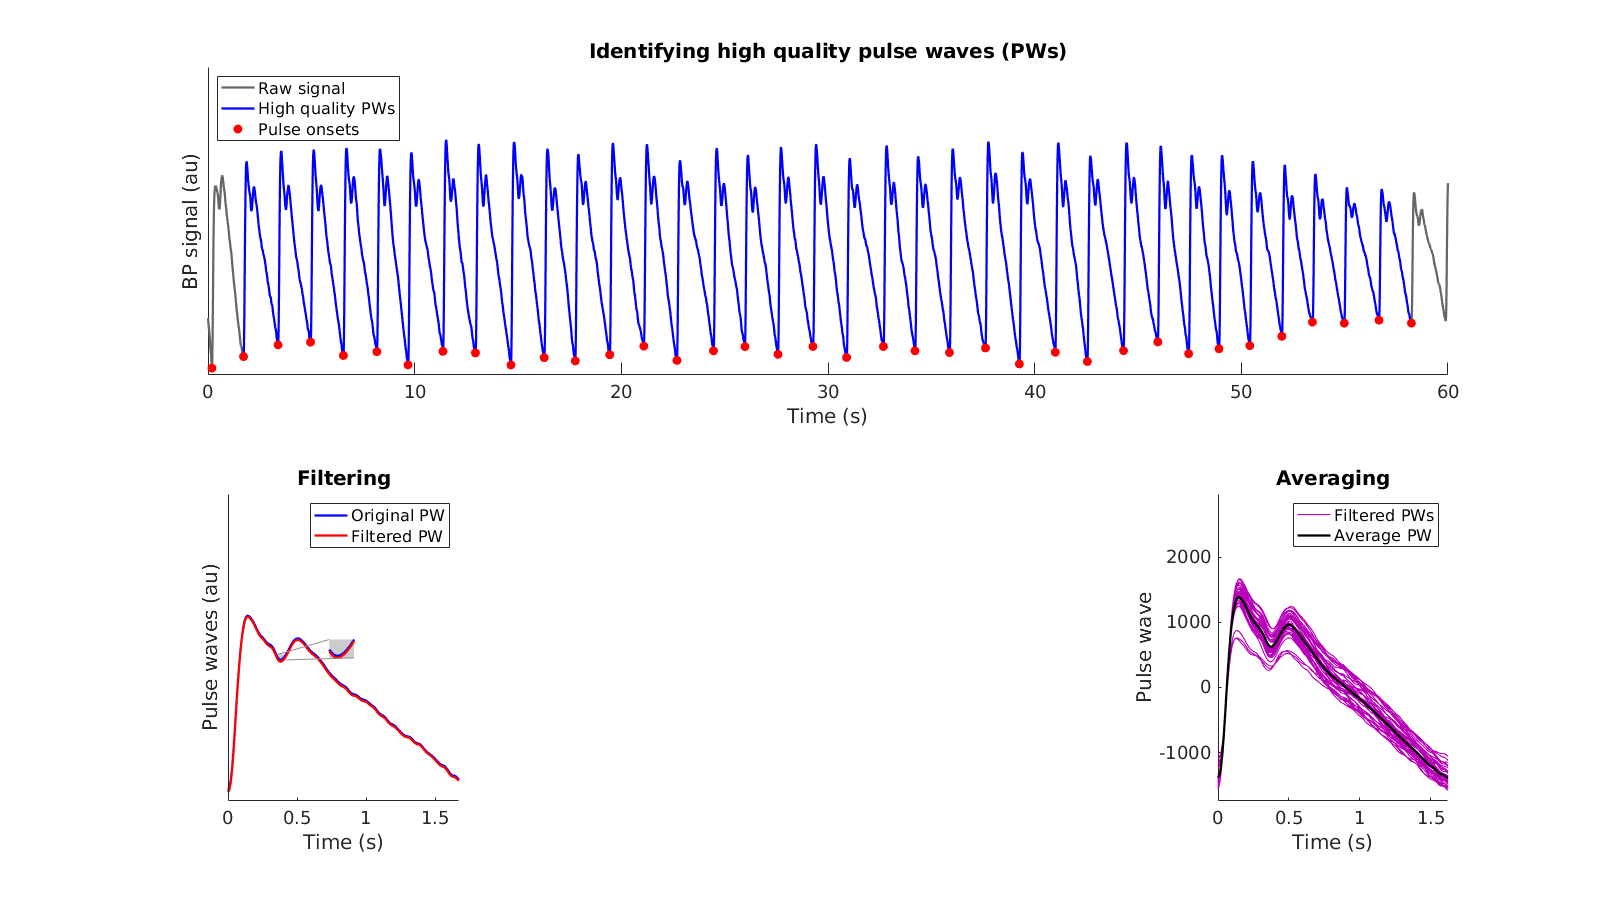

options.downsample =0;
options.calc_average_pw=1;
options.plot_areas =1;
load('PPGdiary1_1_min_sample.mat') % data is obtained from https://peterhcharlton.github.io/ppg-diary/datasets.html
[pw_inds, fid_pts, pulses, sigs] = PulseAnalyse(S,options);

### Ploting the ensamble average

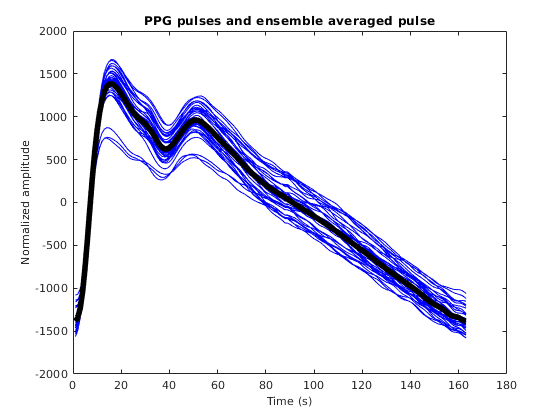

figure, plot(sigs.pws, 'b')
hold on, plot(sigs.ave, 'k', 'lineWidth', 5)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Normalized amplitude', 'FontSize', 10)
title('PPG pulses and ensemble averaged pulse')
 exportgraphics(gcf,"Fig6.21.jpg", 'Resolution',600)

## Visualising realistic signals obtained from red and infrared LEDs

Data is obtained form the finger using the reflective mode PPG. SpO2 is about 96%. It is useful to visualize the data. The fiirst column is the signal from the red PPG and and second column is the signal obtained from the IR PPG. The sampling rate is 250 samples per second.    

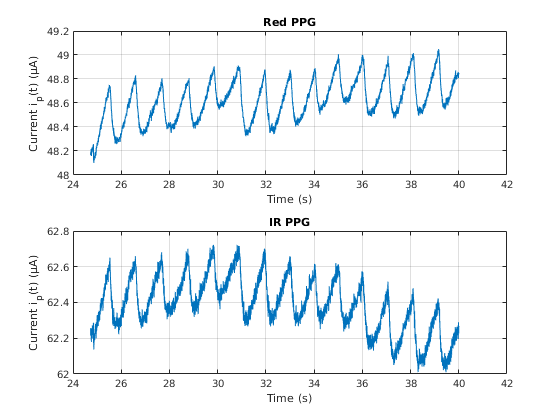

load('PPG_Data1.mat')

fs=250;
t=1/fs:1/fs:length(PPG_Data1)/fs;
start1 =6182;
figure, 
subplot(211) 
plot(t(start1:end),PPG_Data1(start1:end,1))
xlabel('Time (s)', 'FontSize', 10)
title('Red PPG')
ylabel('Current i_p(t) (µA)', 'FontSize', 10)
grid on
subplot(212) , plot(t(start1:end),PPG_Data1(start1:end,2))
xlabel('Time (s)', 'FontSize', 10)
ylabel('Current i_p(t) (µA)', 'FontSize', 10)
title('IR PPG')
grid on
 exportgraphics(gcf,"Fig6.20.jpg", 'Resolution',600)